# Power Split Drive Unit

## Drive with MG1

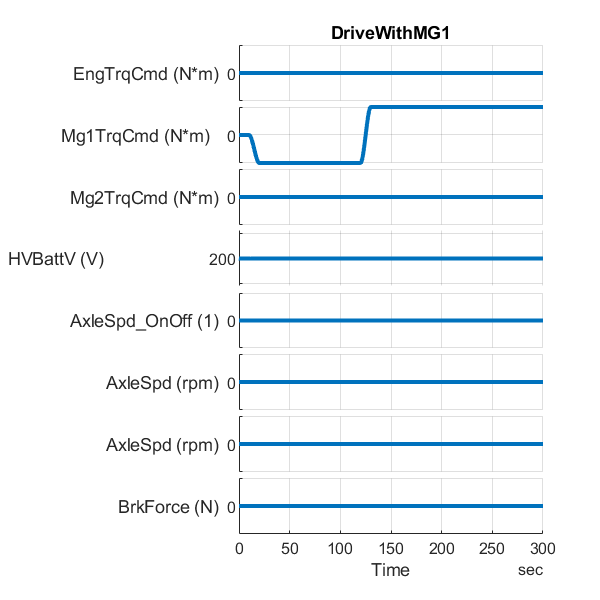

mdl = "PowerSplitDriveUnit_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end

PowerSplitDriveUnit_harness_setup

PSDU_SignalBuilder = PowerSplitDriveUnit_InputSignalBuilder("Plot_tf",true);

InpData = DriveWithMG1(PSDU_SignalBuilder);

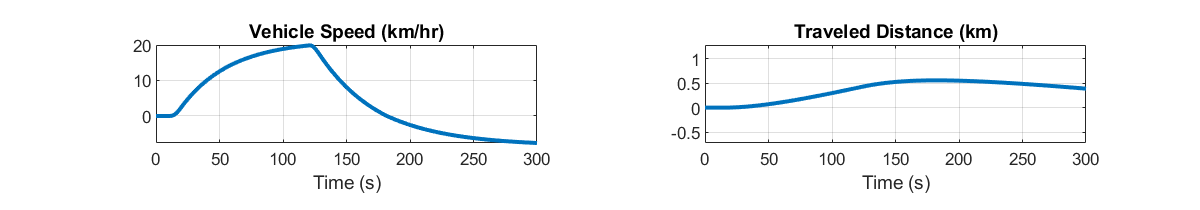

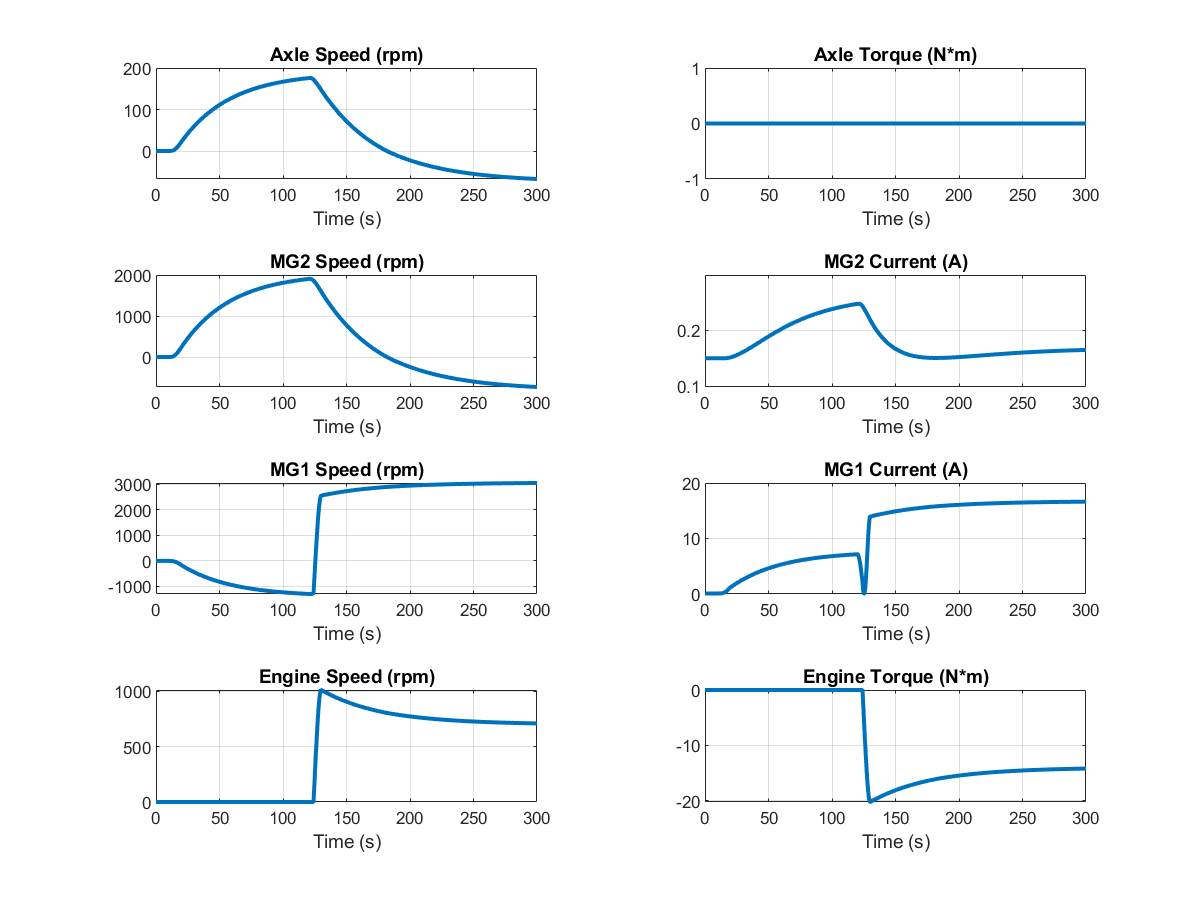

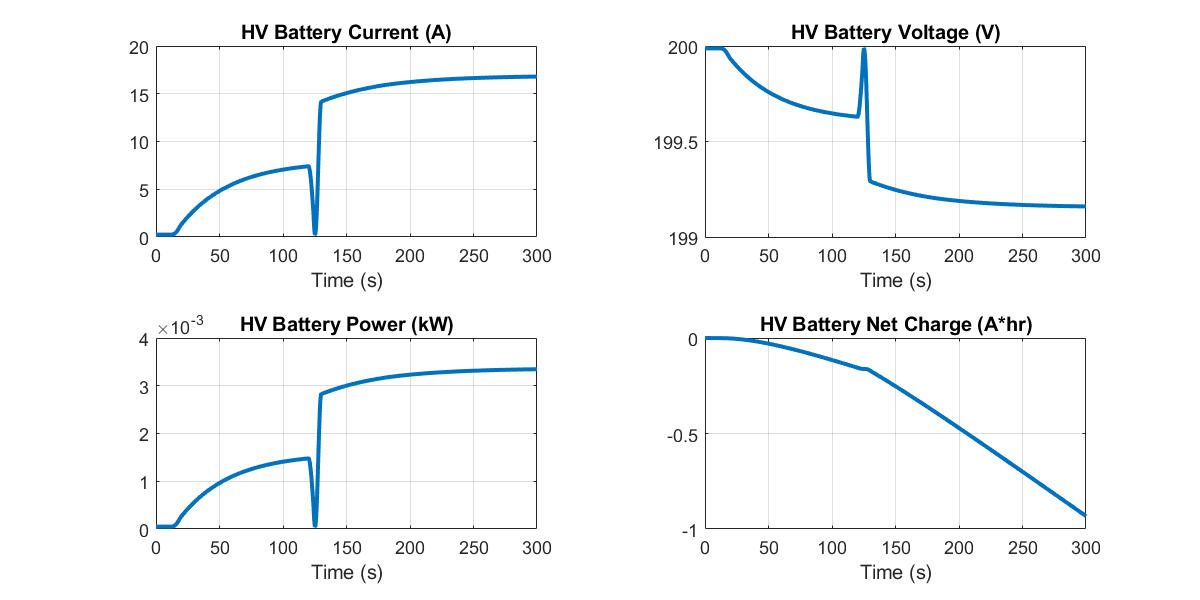


simIn = Simulink.SimulationInput(mdl);
simIn = setVariable(simIn, "PSDU_InputSignals", InpData.Signals);
simIn = setVariable(simIn, "PSDU_InputBus", InpData.Bus);
simIn = setModelParameter(simIn, "StopTime",num2str(InpData.Options.StopTime_s));

simOut = sim(simIn);

PowerSplitDriveUnit_plot_results(simOut.logsout)

*Copyright 2021-2022 The MathWorks, Inc.*